# **Build Model of Battery Pack with Cell Aging**

This example shows how to create and build a Simscape™ system model of a battery pack that includes cell aging in Simscape™ Battery™. Predicting the lifetime of battery cells under a specific application is fundamental to assess warranty risk, develop second-life applications, and perform virtual design verification.

To create the system model of a battery pack, you must first create the `Cell`, `ParallelAssembly`, `Module`, and `ModuleAssembly` objects that comprise the battery pack, and then use the `buildBattery` function. 

This figure shows the overall process to create a battery pack object in a bottom-up approach:

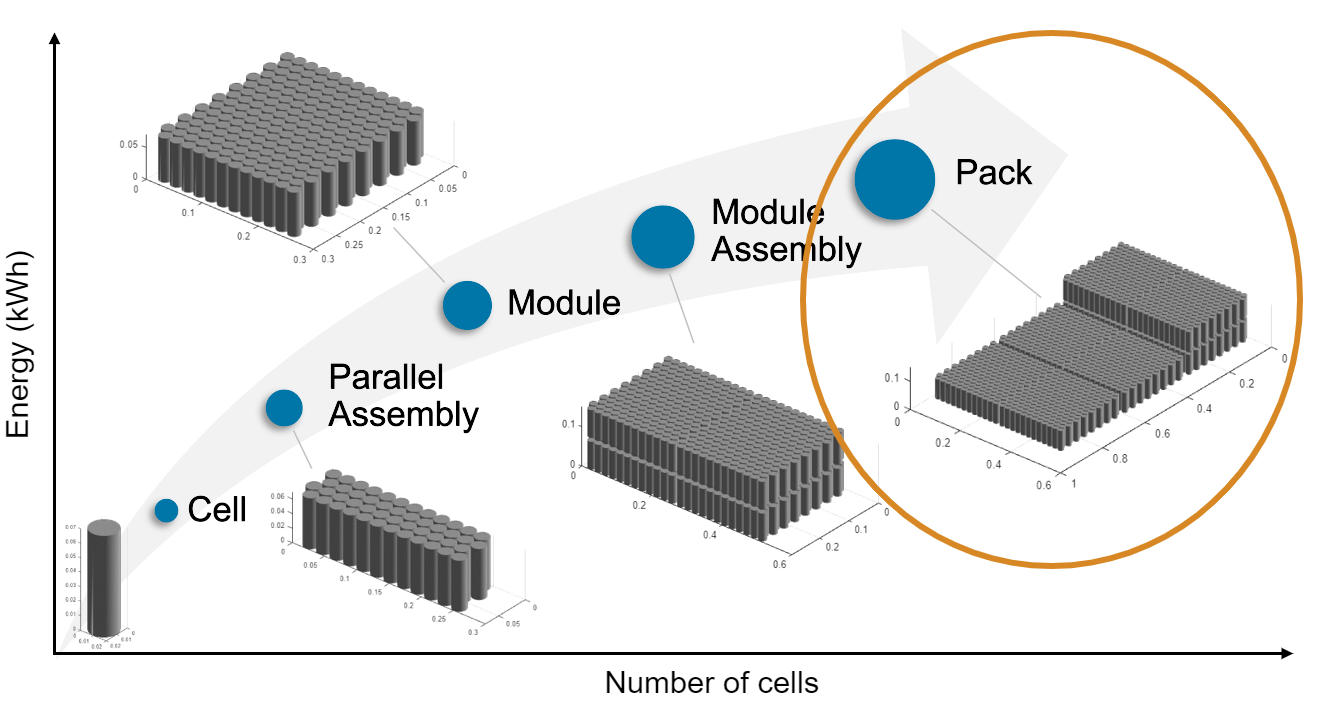

A battery pack comprises multiple module assemblies. These module assemblies, in turn, comprise a number of battery modules connected electrically in series or in parallel. The battery modules are made of multiple parallel assemblies which, in turn, comprise a number of battery cells connected electrically in parallel under a specific topological configuration or geometrical arrangement.

Once you have created your battery pack object, the [buildBattery](docid:battery_ref#mw_09717e3d-8095-4fa5-a313-6bd9a9da8244) function creates a library in your working folder that contains a system model block of the battery pack. You can use this system model as a reference in your simulations. The run-time parameters for these models, such as the battery cell impedance or the battery open-circuit voltage, are defined after the model creation and are therefore not covered by the Battery Pack Builder classes. To define the run-time parameters, you can either specify them in the block mask of the generated Simscape models or use the `MaskParameters` argument of the `buildBattery` function.

## Create Battery `Pack` Object in MATLAB

This section shows how to programmatically generate a battery `Pack` object from the MATLAB® Command Window.

### Create `Cell` Object and Specify Aging Effects

To create the battery `Module` object, first create a `Cell` object of pouch format.

The [PouchGeometry](docid:battery_ref#mw_894c2f15-2ce2-4fc8-9a3b-a9ff19c4a182) object allows you to define the pouch geometrical arrangement of the battery cell. To create the `PouchGeometry` object, use the [`batteryPouchGeometry`](docid:battery_ref#mw_58d9ece9-aa2c-462f-bf85-4a18aab6320f) function.

pouchGeometry = batteryPouchGeometry()

pouchGeometry =   PouchGeometry with properties:

         Length: 0.2300 (m)
      Thickness: 0.0100 (m)
    TabLocation: "Standard"
       TabWidth: 0.0400 (m)
      TabHeight: 0.0300 (m)
         Height: 0.2800 (m)


For more information on the possible geometrical arrangements of a battery cell, see the [CylindricalGeometry](docid:battery_ref#mw_c5224532-2b73-4d0f-b268-6be8da8acd16) and [PrismaticGeometry](docid:battery_ref#mw_ec08796b-482d-4e27-8ada-0dd1efd7a1af) documentation pages.

Now use this `PouchGeometry` object to create a pouch battery cell.

pouchCell = batteryCell(pouchGeometry)

pouchCell =   Cell with properties:

            Geometry: [1×1 simscape.battery.builder.PouchGeometry]
    CellModelOptions: [1×1 simscape.battery.builder.CellModelBlock]
                Mass: 0.1000 (kg)
            Capacity: 5 (A*hr)
              Energy: 50 (W*hr)

Show all properties


For more information, see the [Cell](docid:battery_ref#mw_2d026fef-ba0c-4c1a-92e1-11623b831691) documentation page.

The `Cell` object allows you to simulate the aging effects of the battery cell by specifying these properties:

- `prm_age_capacity` — Capacity calendar aging. This property allows you to decide whether to model the calendar aging effects on the capacity of a battery cell.

- `prm_age_resistance` — Internal resistance calendar aging. This property allows you to decide whether to model the calendar aging effects on the internal resistance of a battery cell.

- `prm_age_modeling` — Modeling option. This property allows you to specify how to mathematically model the aging effects on the capacity and internal resistance of a battery cell.

To simulate the cycling aging effects of the battery cell, in the `BlockParameters` property of the `CellModelOptions` property of the `Cell` object, set the `prm_fade` property to `"equations"`.

pouchCell.CellModelOptions.BlockParameters.prm_fade = "equations";

The `Cell` object also allows you to simulate the thermal effects of the battery cell by using a simple 1-D model. To simulate the thermal effects of the battery cell, in the `BlockParameters` property of the `CellModelOptions` property of the `Cell` object, set the `thermal_port` property to `"model"`.

pouchCell.CellModelOptions.BlockParameters.thermal_port = "model";

### Create `ParallelAssembly` Object

A battery parallel assembly comprises multiple battery cells connected electrically in parallel under a specific topological configuration or geometrical arrangement. In this example, you create a parallel assembly of three pouch cells. 

To create the `ParallelAssembly` object, use the [`batteryParallelAssembly`](docid:battery_ref#mw_4dcd3a36-27f9-4286-afbe-bfabd21f1b76) function. Define the `Cell` object as the first argument and the number of cells in parallel as the second argument.

parallelAssembly = batteryParallelAssembly(pouchCell,...
    3,StackingAxis="X");

For more information, see the [ParallelAssembly](docid:battery_ref#mw_a3e68eac-4afa-4391-b3ee-d464d818e28d) documentation page.

### Create `Module` Object

A battery module comprises multiple parallel assemblies connected in series. In this example, you create a battery module of 4 parallel assemblies stacked along the X axis, with an intergap between each assembly of 0.005 meters.

To create the `Module` object, use the [`batteryModule`](docid:battery_ref#mw_e3820991-1488-40bc-8d4d-e99c91843474) function. Specify the `ParallelAssembly` object as the first argument and the number of parallel assemblies connected in series as the second argument. To define the additional properties, use the name-value arguments `InterParallelAssemblyGap` and `StackingAxis`.

module = batteryModule(parallelAssembly,4,...
    InterParallelAssemblyGap=simscape.Value(0.005,"m"), ...
    StackingAxis="X");

For more information, see the [Module](docid:battery_ref#mw_7667d6f8-0894-4334-b1b0-07b10449021a) documentation page.

### Create `ModuleAssembly` Object

A battery module assembly comprises multiple battery modules connected in series or in parallel. In this example, you create a battery module assembly of five identical modules with an intergap between each module equal to 0.1 meters. By default, the `ModuleAssembly` object electrically connects the modules in series.

To create the `ModuleAssembly` object, use the [`batteryModuleAssembly`](docid:battery_ref#mw_a172e733-32b4-4326-a4a5-862e2ba73e09) function and specify the `Module` objects as the first argument. To define the additional properties, use the name-value arguments `InterModuleGap` and `StackingAxis`.

moduleAssembly = batteryModuleAssembly(repmat(module,1,5),...
    InterModuleGap=simscape.Value(0.1,"m"), ...
    StackingAxis="Y");

For more information, see the [ModuleAssembly](docid:battery_ref#mw_a7e69edd-6e39-41fa-b32b-b94ef3ffdc0f) documentation page.

### Create `Pack` Object

You now have all the foundational elements to create your battery pack. A battery pack comprises multiple module assemblies connected in series or in parallel. In this example, you create a battery pack of five identical module assemblies with an intergap between each module assembly of 0.01 meters and a coolant thermal path.

To create the `Pack` object, use the [`batteryPack`](docid:battery_ref#mw_8968c3f3-7808-42ad-a1df-04d6f41efb19) function and define the `ModuleAssembly` objects as the first argument. To define the additional properties, use the name-value arguments `InterModuleAssemblyGap` and `CoolantThermalPath`. Setting the `CoolantThermalPath` property automatically propagates its value to all the subcomponent battery objects inside this Pack object. However, this change does not propagate to the other battery objects in your MATLAB workspace.

pack = batteryPack(repmat(moduleAssembly,1,5),...
    InterModuleAssemblyGap=simscape.Value(0.01,"m"),...
    CoolantThermalPath="CellBasedThermalResistance");

For more information, see the [Pack](docid:battery_ref#mw_733fa856-2f6d-4d21-abdd-e65b3e04e90a) documentation page.

## Visualize Battery Pack and Check Model Resolution

To visualize the battery pack before you build the system model and to view its model resolution, create the figure where you want to visualize your pack and then use the [`batteryChart`](docid:battery_ref#mw_dbe5f15f-3424-47d4-8766-393cc212cfa7) function. To view the model resolution of the module, define the `SimulationStrategyVisible` name-value argument as `"On"`.

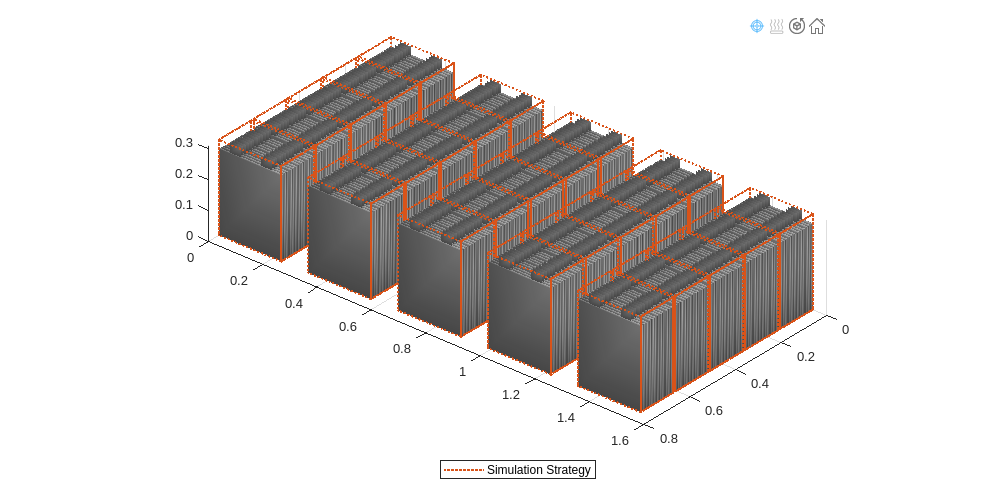

f = figure(Color="w",Position=[0 0 1000 500]);
packChart = batteryChart(f,pack, ...
    SimulationStrategyVisible="on");

To add default axis labels to the battery plot, use the `setDefaultLabels` method of the `BatteryChart` object.

For more information about the BatteryChart object, see the [BatteryChart](docid:battery_ref#mw_dbe5f15f-3424-47d4-8766-393cc212cfa7) documentation page.

## Build Simscape Model for the Battery Pack Object

After you have created your battery objects, you need to convert them into Simscape models to use them in block diagrams. You can then use these models as reference for your system integration and requirement evaluation, cooling system design, control strategy development, hardware-in-the-loop, and many more applications.

buildBattery(pack,LibraryName="packAgingExample")

This function creates the `packAgingExample_lib` and `packAgingExample` SLX library files in your working directory. The `packAgingExample_lib` library contains the Modules and ParallelAssemblies sublibraries. 

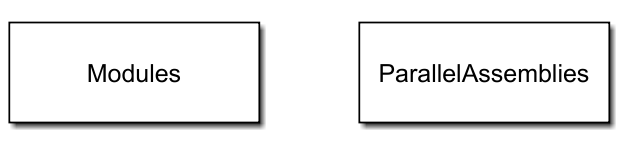

To access the Simscape models of your M`odule` and `ParallelAssembly` objects, open the `packAgingExample_lib`. SLX file, double-click the sublibrary, and drag the Simscape blocks in your model.

The `packAgingExample` library contains the Simscape models of your `ModuleAssembly` and `Pack` objects.

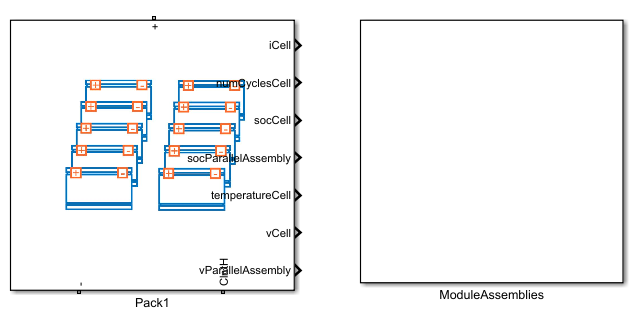

The Simscape models of your `ModuleAssembly` and `Pack` objects are subsystems. You can look inside these subsystems by opening the `packLibrary` SLX file and double-click the subsystem.

To see how to evaluate a new and end-of-life (EOL) lithium-ion battery pack, see the [Thermal Analysis for New and Aged Battery Packs](docid:battery_ug#example-batt_thermal_analysis_new_aged_battery) example.

## Explore Battery Pack and Build Model in Battery Builder App 

In this example, you programmatically created the battery pack and all its subcomponents by calling the relevant objects and functions in the MATLAB Command Window. Alternatively, if you prefer a more interactive and visual approach, you can use the [Battery Builder](docid:battery_ref#mw_df55e9aa-c1ab-4c71-b0e0-7d755cbe0b59) app. Using this app, you can interactively import existing battery objects or build them from scratch, explore and edit properties, and view the battery hierarchy and 3-D visualization. You can then build the Simscape system model of your objects and use it as a reference in your simulations. You can also export the objects in your workspace. To learn how to use the Battery Builder app to generate battery objects and build Simscape models, see the [Get Started with Battery Builder App](docid:battery_ug#example-batt_get_started_battery_builder_app) example.

Explore the battery pack that you created in this example. Open the Battery Builder app. On the **Apps** tab, under **Simscape**, click the **Battery Builder** icon. Alternatively, you can open the app from the command line:

batteryBuilder

Import the battery pack object from the `packAgingExample` MAT file. Under the **Battery Builder** tab, in the **Import** section of the toolstrip, click **Import**. Then click **Import from MAT-file **and load the `packAgingExample` MAT file.

The Battery Builder app now comprises a `Pack` object and each of its subcomponents.

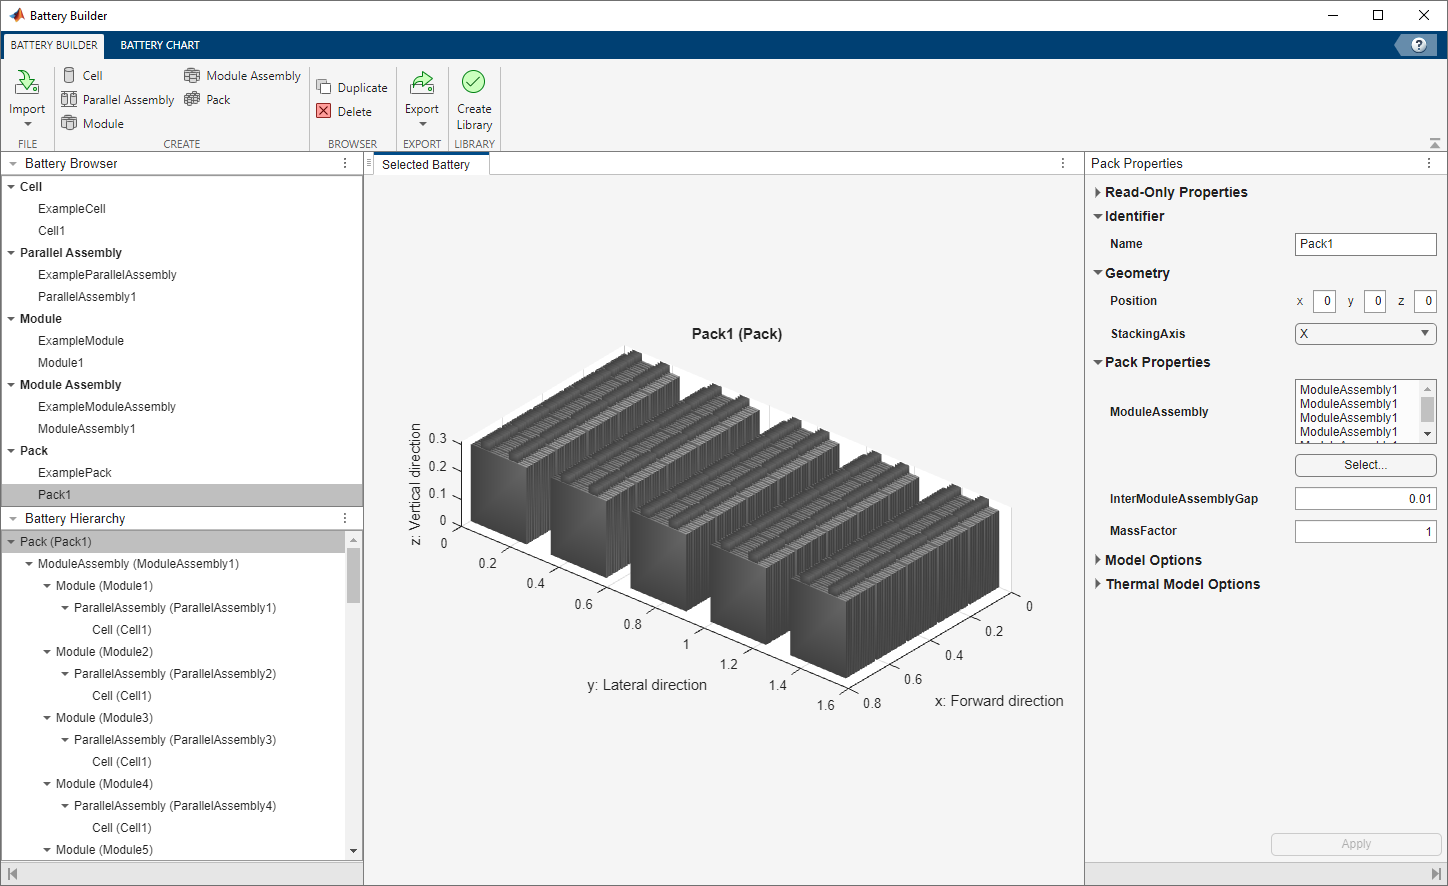

The **Battery Browser** panel on the left of the app contains all the battery objects in the current active session of the app. You can select an object, visualize it in the **Selected Battery** tab, check its hierarchy and child objects in the **Battery Hierarchy** panel, and edit its properties in the **Properties** panel on the right of the app.

You can edit properties of the plot under the **Battery Chart** tab, such as the axes labels, axes direction, title of the plot, and lights. You can also check the current simulation strategy and model resolution of the selected battery object. To visualize the simulation strategy in the plot, in the **Simulation Strategy** section of the toolstrip, check the **Visible** box.

Finally, if you modified your battery object and you want to create a library model of the updated `Pack` object, under the **Battery Builder** tab, in the **Library** section of the toolstrip, click **Create Library**. In the new window, specify the folder in which you want to save the library, the library name, and whether to use numeric values or variable names for the mask parameters and mask initial targets. 

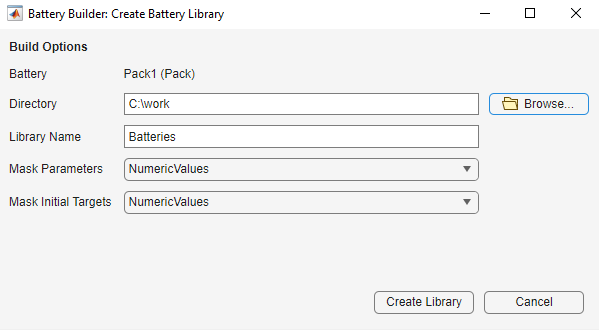

Click **Create Library** to generate the updated library model of your battery object in the specified folder. Open this model to access your battery objects as Simscape blocks that you can use as a starting point for architecture evaluation in early development stages, software and hardware development, system integration and requirement evaluation, cooling system design, control strategy development, hardware-in-the-loop, and many more applications.

*Copyright 2022-2023 The MathWorks, Inc.*